## Create Image Datastore

clc;
clear; 

imageSize = [224 224];

Train = imageDatastore("Train\", "IncludeSubfolders",true, "LabelSource","foldernames");
Train_aug = augmentedImageDatastore(imageSize,Train);

numClasses = numel(categories(Train.Labels));

## Network definition

net = resnet50;
lgraph = layerGraph(net);

fc = fullyConnectedLayer(2,"Name","new_fc")

fc =   FullyConnectedLayer with properties:

          Name: 'new_fc'

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 2

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


lgraph = replaceLayer(lgraph,"fc1000",fc)

lgraph =   LayerGraph with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'ClassificationLayer_fc1000'}



out = classificationLayer("Name","new_out")

out =   ClassificationOutputLayer with properties:

            Name: 'new_out'
         Classes: 'auto'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'


lgraph = replaceLayer(lgraph,"ClassificationLayer_fc1000",out)

lgraph =   LayerGraph with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'new_out'}


## Training Option

batch_size = 16;
Max_epochs = 8;

options = trainingOptions('adam', ...
    'Plots','training-progress',...
    "Verbose", true, ...
    "VerboseFrequency", 10,...
    "MaxEpochs", Max_epochs,...
    "MiniBatchSize", batch_size,...
    "Shuffle","every-epoch",...
    "InitialLearnRate", 0.0005,...
    "LearnRateSchedule","piecewise", ...
    'LearnRateDropFactor',0.7, ...
    'LearnRateDropPeriod',3, ...
    "L2Regularization", 0.0001,...
    "ExecutionEnvironment","auto")

options =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 5.0000e-04
             LearnRateSchedule: 'piecewise'
           LearnRateDropFactor: 0.7000
           LearnRateDropPeriod: 3
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 8
                 MiniBatchSize: 16
                       Verbose: 1
              VerboseFrequency: 10
                ValidationData: []
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'every-epoch'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
                         Plots

## Training Step

Training on single CPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:07 |       56.25% |       0.6751 |          0.0005 |


|       1 |          10 |       00:01:01 |       75.00% |       0.9934 |          0.0005 |


|       1 |          20 |       00:02:00 |       68.75% |       1.0175 |          0.0005 |


|       1 |          30 |       00:03:00 |       62.50% |       0.8892 |          0.0005 |


|       1 |          40 |       00:03:59 |       62.50% |       0.8531 |          0.0005 |


|       1 |          50 |       00:04:58 |       87.50% |       0.3843 |          0.0005 |


|       1 |          60 |       00:05:58 |       68.75% |       1.2210 |          0.0005 |


|       1 |          70 |       00:06:57 |       75.00% |       0.4102 |          0.0005 |


|       1 |          80 |       00:07:56 |       93.75% |       0.2708 |          0.0005 |


|       1 |          90 |       00:08:55 |       93.75% |       0.1807 |          0.0005 |


|       1 |         100 |       00:09:54 |       87.50% |       0.5053 |          0.0005 |


|       1 |         110 |       00:11:00 |       93.75% |       0.2122 |          0.0005 |


|       1 |         120 |       00:12:01 |       93.75% |       0.1732 |          0.0005 |


|       1 |         130 |       00:13:03 |       93.75% |       0.2121 |          0.0005 |


|       1 |         140 |       00:14:04 |      100.00% |       0.0722 |          0.0005 |


|       1 |         150 |       00:15:05 |       87.50% |       0.1380 |          0.0005 |


|       1 |         160 |       00:16:05 |       87.50% |       0.2900 |          0.0005 |


|       1 |         170 |       00:17:07 |      100.00% |       0.0283 |          0.0005 |


|       1 |         180 |       00:18:10 |      100.00% |       0.0359 |          0.0005 |


|       1 |         190 |       00:19:13 |       93.75% |       0.0702 |          0.0005 |


|       1 |         200 |       00:20:23 |       87.50% |       0.2401 |          0.0005 |


|       1 |         210 |       00:21:28 |      100.00% |       0.0770 |          0.0005 |


|       1 |         220 |       00:22:30 |      100.00% |       0.0610 |          0.0005 |


|       1 |         230 |       00:23:31 |      100.00% |       0.0380 |          0.0005 |


|       2 |         240 |       00:24:33 |       93.75% |       0.1633 |          0.0005 |


|       2 |         250 |       00:25:33 |      100.00% |       0.0916 |          0.0005 |


|       2 |         260 |       00:26:36 |      100.00% |       0.0221 |          0.0005 |


|       2 |         270 |       00:27:37 |       93.75% |       0.0673 |          0.0005 |


|       2 |         280 |       00:28:38 |      100.00% |       0.0329 |          0.0005 |


|       2 |         290 |       00:29:38 |       87.50% |       0.3115 |          0.0005 |


|       2 |         300 |       00:30:41 |      100.00% |       0.0661 |          0.0005 |


|       2 |         310 |       00:31:40 |      100.00% |       0.0290 |          0.0005 |


|       2 |         320 |       00:32:39 |      100.00% |       0.0114 |          0.0005 |


|       2 |         330 |       00:33:38 |      100.00% |       0.0220 |          0.0005 |


|       2 |         340 |       00:34:38 |       93.75% |       0.1503 |          0.0005 |


|       2 |         350 |       00:35:38 |      100.00% |       0.0992 |          0.0005 |


|       2 |         360 |       00:36:37 |       93.75% |       0.0948 |          0.0005 |


|       2 |         370 |       00:37:36 |       93.75% |       0.0984 |          0.0005 |


|       2 |         380 |       00:38:36 |      100.00% |       0.0134 |          0.0005 |


|       2 |         390 |       00:39:35 |      100.00% |       0.0065 |          0.0005 |


|       2 |         400 |       00:40:34 |      100.00% |       0.0481 |          0.0005 |


|       2 |         410 |       00:41:33 |      100.00% |       0.0035 |          0.0005 |


|       2 |         420 |       00:42:38 |       93.75% |       0.1370 |          0.0005 |


|       2 |         430 |       00:43:39 |      100.00% |       0.0132 |          0.0005 |


|       2 |         440 |       00:44:39 |      100.00% |       0.0456 |          0.0005 |


|       2 |         450 |       00:45:39 |      100.00% |       0.0037 |          0.0005 |


|       2 |         460 |       00:46:40 |      100.00% |       0.0788 |          0.0005 |


|       3 |         470 |       00:47:41 |      100.00% |       0.0094 |          0.0005 |


|       3 |         480 |       00:48:40 |      100.00% |       0.0544 |          0.0005 |


|       3 |         490 |       00:49:40 |      100.00% |       0.0243 |          0.0005 |


|       3 |         500 |       00:50:39 |       93.75% |       0.1615 |          0.0005 |


|       3 |         510 |       00:51:40 |      100.00% |       0.0028 |          0.0005 |


|       3 |         520 |       00:52:40 |      100.00% |       0.0014 |          0.0005 |


|       3 |         530 |       00:53:39 |      100.00% |       0.0395 |          0.0005 |


|       3 |         540 |       00:54:40 |      100.00% |       0.0091 |          0.0005 |


|       3 |         550 |       00:55:39 |      100.00% |       0.0446 |          0.0005 |


|       3 |         560 |       00:56:38 |      100.00% |       0.0038 |          0.0005 |


|       3 |         570 |       00:57:38 |      100.00% |       0.0099 |          0.0005 |


|       3 |         580 |       00:58:39 |      100.00% |       0.0309 |          0.0005 |


|       3 |         590 |       00:59:38 |      100.00% |       0.0053 |          0.0005 |


|       3 |         600 |       01:00:38 |      100.00% |       0.0038 |          0.0005 |


|       3 |         610 |       01:01:37 |      100.00% |       0.0003 |          0.0005 |


|       3 |         620 |       01:02:36 |      100.00% |       0.0011 |          0.0005 |


|       3 |         630 |       01:03:37 |      100.00% |       0.0115 |          0.0005 |


|       3 |         640 |       01:04:37 |      100.00% |       0.0012 |          0.0005 |


|       3 |         650 |       01:05:37 |      100.00% |       0.0014 |          0.0005 |


|       3 |         660 |       01:06:36 |       93.75% |       0.1233 |          0.0005 |


|       3 |         670 |       01:07:35 |       93.75% |       0.0583 |          0.0005 |


|       3 |         680 |       01:08:35 |      100.00% |       0.0245 |          0.0005 |


|       3 |         690 |       01:09:35 |      100.00% |       0.0080 |          0.0005 |


|       4 |         700 |       01:10:34 |      100.00% |       0.0006 |          0.0004 |


|       4 |         710 |       01:11:34 |      100.00% |       0.0002 |          0.0004 |


|       4 |         720 |       01:12:34 |      100.00% |       0.0055 |          0.0004 |


|       4 |         730 |       01:13:50 |      100.00% |       0.0002 |          0.0004 |


|       4 |         740 |       01:14:52 |      100.00% |       0.0002 |          0.0004 |


|       4 |         750 |       01:15:57 |      100.00% |       0.0072 |          0.0004 |


|       4 |         760 |       01:16:56 |      100.00% |       0.0032 |          0.0004 |


|       4 |         770 |       01:17:58 |      100.00% |       0.0030 |          0.0004 |


|       4 |         780 |       01:18:57 |      100.00% |       0.0014 |          0.0004 |


|       4 |         790 |       01:19:55 |      100.00% |       0.0002 |          0.0004 |


|       4 |         800 |       01:20:53 |      100.00% |       0.0022 |          0.0004 |


|       4 |         810 |       01:21:51 |      100.00% |       0.0018 |          0.0004 |


|       4 |         820 |       01:22:52 |      100.00% |       0.0004 |          0.0004 |


|       4 |         830 |       01:23:52 |      100.00% |       0.0179 |          0.0004 |


|       4 |         840 |       01:24:52 |      100.00% |       0.0204 |          0.0004 |


|       4 |         850 |       01:25:52 |      100.00% |       0.0425 |          0.0004 |


|       4 |         860 |       01:26:52 |      100.00% |       0.0155 |          0.0004 |


|       4 |         870 |       01:27:53 |      100.00% |       0.0014 |          0.0004 |


|       4 |         880 |       01:28:55 |      100.00% |       0.0167 |          0.0004 |


|       4 |         890 |       01:29:55 |      100.00% |       0.0243 |          0.0004 |


|       4 |         900 |       01:30:53 |       93.75% |       0.2321 |          0.0004 |


|       4 |         910 |       01:31:51 |      100.00% |       0.0031 |          0.0004 |


|       4 |         920 |       01:32:49 |      100.00% |       0.0007 |          0.0004 |


|       5 |         930 |       01:33:48 |      100.00% |       0.0017 |          0.0004 |


|       5 |         940 |       01:34:46 |      100.00% |       0.0054 |          0.0004 |


|       5 |         950 |       01:35:44 |      100.00% |       0.0042 |          0.0004 |


|       5 |         960 |       01:36:42 |      100.00% |       0.0005 |          0.0004 |


|       5 |         970 |       01:37:40 |      100.00% |       0.0005 |          0.0004 |


|       5 |         980 |       01:38:38 |      100.00% |       0.0007 |          0.0004 |


|       5 |         990 |       01:39:37 |      100.00% |       0.0001 |          0.0004 |


|       5 |        1000 |       01:40:35 |       93.75% |       0.0514 |          0.0004 |


|       5 |        1010 |       01:41:35 |      100.00% |       0.0033 |          0.0004 |


|       5 |        1020 |       01:42:34 |      100.00% |   9.2329e-05 |          0.0004 |


|       5 |        1030 |       01:43:32 |      100.00% |       0.0253 |          0.0004 |


|       5 |        1040 |       01:44:30 |      100.00% |       0.0001 |          0.0004 |


|       5 |        1050 |       01:45:28 |      100.00% |       0.0088 |          0.0004 |


|       5 |        1060 |       01:46:27 |       93.75% |       0.0676 |          0.0004 |


|       5 |        1070 |       01:47:25 |      100.00% |       0.0015 |          0.0004 |


|       5 |        1080 |       01:48:23 |      100.00% |       0.0002 |          0.0004 |


|       5 |        1090 |       01:49:21 |      100.00% |       0.0063 |          0.0004 |


|       5 |        1100 |       01:50:19 |      100.00% |   1.9343e-05 |          0.0004 |


|       5 |        1110 |       01:51:17 |      100.00% |       0.0003 |          0.0004 |


|       5 |        1120 |       01:52:15 |      100.00% |       0.0052 |          0.0004 |


|       5 |        1130 |       01:53:13 |      100.00% |       0.0002 |          0.0004 |


|       5 |        1140 |       01:54:13 |      100.00% |       0.0007 |          0.0004 |


|       5 |        1150 |       01:55:12 |      100.00% |       0.0164 |          0.0004 |


|       5 |        1160 |       01:56:10 |      100.00% |       0.0012 |          0.0004 |


|       6 |        1170 |       01:57:08 |      100.00% |       0.0053 |          0.0004 |


|       6 |        1180 |       01:58:06 |      100.00% |       0.0033 |          0.0004 |


|       6 |        1190 |       01:59:04 |      100.00% |       0.0028 |          0.0004 |


|       6 |        1200 |       02:00:03 |      100.00% |       0.0089 |          0.0004 |


|       6 |        1210 |       02:01:01 |      100.00% |       0.0002 |          0.0004 |


|       6 |        1220 |       02:01:59 |      100.00% |   4.2743e-05 |          0.0004 |


|       6 |        1230 |       02:02:57 |      100.00% |       0.0029 |          0.0004 |


|       6 |        1240 |       02:03:55 |      100.00% |       0.0018 |          0.0004 |


|       6 |        1250 |       02:04:52 |      100.00% |       0.0002 |          0.0004 |


|       6 |        1260 |       02:05:50 |      100.00% |   8.7781e-05 |          0.0004 |


|       6 |        1270 |       02:06:48 |      100.00% |       0.0008 |          0.0004 |


|       6 |        1280 |       02:07:46 |      100.00% |   9.0687e-05 |          0.0004 |


|       6 |        1290 |       02:08:44 |      100.00% |       0.0017 |          0.0004 |


|       6 |        1300 |       02:09:42 |      100.00% |       0.0001 |          0.0004 |


|       6 |        1310 |       02:10:40 |      100.00% |       0.0013 |          0.0004 |


|       6 |        1320 |       02:11:38 |      100.00% |       0.0037 |          0.0004 |


|       6 |        1330 |       02:12:36 |      100.00% |       0.0118 |          0.0004 |


|       6 |        1340 |       02:13:34 |      100.00% |       0.0001 |          0.0004 |


|       6 |        1350 |       02:14:33 |      100.00% |       0.0087 |          0.0004 |


|       6 |        1360 |       02:15:31 |      100.00% |       0.0027 |          0.0004 |


|       6 |        1370 |       02:16:29 |      100.00% |       0.0013 |          0.0004 |


|       6 |        1380 |       02:17:27 |      100.00% |       0.0007 |          0.0004 |


|       6 |        1390 |       02:18:25 |      100.00% |       0.0019 |          0.0004 |


|       7 |        1400 |       02:19:23 |      100.00% |       0.0170 |          0.0002 |


|       7 |        1410 |       02:20:22 |      100.00% |   8.2032e-06 |          0.0002 |


|       7 |        1420 |       02:21:20 |      100.00% |       0.0039 |          0.0002 |


|       7 |        1430 |       02:22:18 |      100.00% |   6.8016e-05 |          0.0002 |


|       7 |        1440 |       02:23:16 |      100.00% |       0.0001 |          0.0002 |


|       7 |        1450 |       02:24:15 |      100.00% |       0.0024 |          0.0002 |


|       7 |        1460 |       02:25:13 |      100.00% |       0.0010 |          0.0002 |


|       7 |        1470 |       02:26:11 |      100.00% |   8.4166e-05 |          0.0002 |


|       7 |        1480 |       02:27:09 |      100.00% |       0.0001 |          0.0002 |


|       7 |        1490 |       02:28:07 |      100.00% |       0.0014 |          0.0002 |


|       7 |        1500 |       02:29:06 |      100.00% |       0.0002 |          0.0002 |


|       7 |        1510 |       02:30:04 |      100.00% |       0.0001 |          0.0002 |


|       7 |        1520 |       02:31:02 |      100.00% |   7.5262e-05 |          0.0002 |


|       7 |        1530 |       02:32:00 |      100.00% |       0.0079 |          0.0002 |


|       7 |        1540 |       02:32:58 |      100.00% |       0.0002 |          0.0002 |


|       7 |        1550 |       02:33:59 |      100.00% |       0.0188 |          0.0002 |


|       7 |        1560 |       02:35:03 |      100.00% |       0.0009 |          0.0002 |


|       7 |        1570 |       02:36:07 |      100.00% |       0.0026 |          0.0002 |


|       7 |        1580 |       02:37:10 |      100.00% |       0.0008 |          0.0002 |


|       7 |        1590 |       02:38:14 |      100.00% |       0.0001 |          0.0002 |


|       7 |        1600 |       02:39:13 |      100.00% |   4.9779e-05 |          0.0002 |


|       7 |        1610 |       02:40:12 |      100.00% |       0.0002 |          0.0002 |


|       7 |        1620 |       02:41:10 |      100.00% |       0.0001 |          0.0002 |


|       8 |        1630 |       02:42:09 |      100.00% |       0.0002 |          0.0002 |


|       8 |        1640 |       02:43:08 |      100.00% |   6.3938e-05 |          0.0002 |


|       8 |        1650 |       02:44:06 |      100.00% |       0.0086 |          0.0002 |


|       8 |        1660 |       02:45:05 |      100.00% |       0.0033 |          0.0002 |


|       8 |        1670 |       02:46:03 |       93.75% |       0.0488 |          0.0002 |


|       8 |        1680 |       02:47:01 |      100.00% |   6.0131e-05 |          0.0002 |


|       8 |        1690 |       02:47:59 |      100.00% |       0.0087 |          0.0002 |


|       8 |        1700 |       02:48:58 |      100.00% |       0.0045 |          0.0002 |


|       8 |        1710 |       02:49:56 |      100.00% |   8.9111e-06 |          0.0002 |


|       8 |        1720 |       02:50:54 |      100.00% |       0.0008 |          0.0002 |


|       8 |        1730 |       02:51:53 |      100.00% |       0.0005 |          0.0002 |


|       8 |        1740 |       02:52:51 |      100.00% |       0.0001 |          0.0002 |


|       8 |        1750 |       02:53:49 |      100.00% |       0.0108 |          0.0002 |


|       8 |        1760 |       02:54:47 |      100.00% |       0.0002 |          0.0002 |


|       8 |        1770 |       02:55:45 |      100.00% |       0.0002 |          0.0002 |


|       8 |        1780 |       02:56:44 |      100.00% |       0.0001 |          0.0002 |


|       8 |        1790 |       02:57:42 |      100.00% |       0.0066 |          0.0002 |


|       8 |        1800 |       02:58:40 |      100.00% |       0.0004 |          0.0002 |


|       8 |        1810 |       02:59:38 |      100.00% |   5.8659e-05 |          0.0002 |


|       8 |        1820 |       03:00:36 |      100.00% |       0.0005 |          0.0002 |


|       8 |        1830 |       03:01:35 |      100.00% |   4.4696e-05 |          0.0002 |


|       8 |        1840 |       03:02:33 |      100.00% |       0.0012 |          0.0002 |


|       8 |        1850 |       03:03:31 |      100.00% |       0.0110 |          0.0002 |


|       8 |        1856 |       03:04:06 |      100.00% |       0.0001 |          0.0002 |
|========================================================================================|


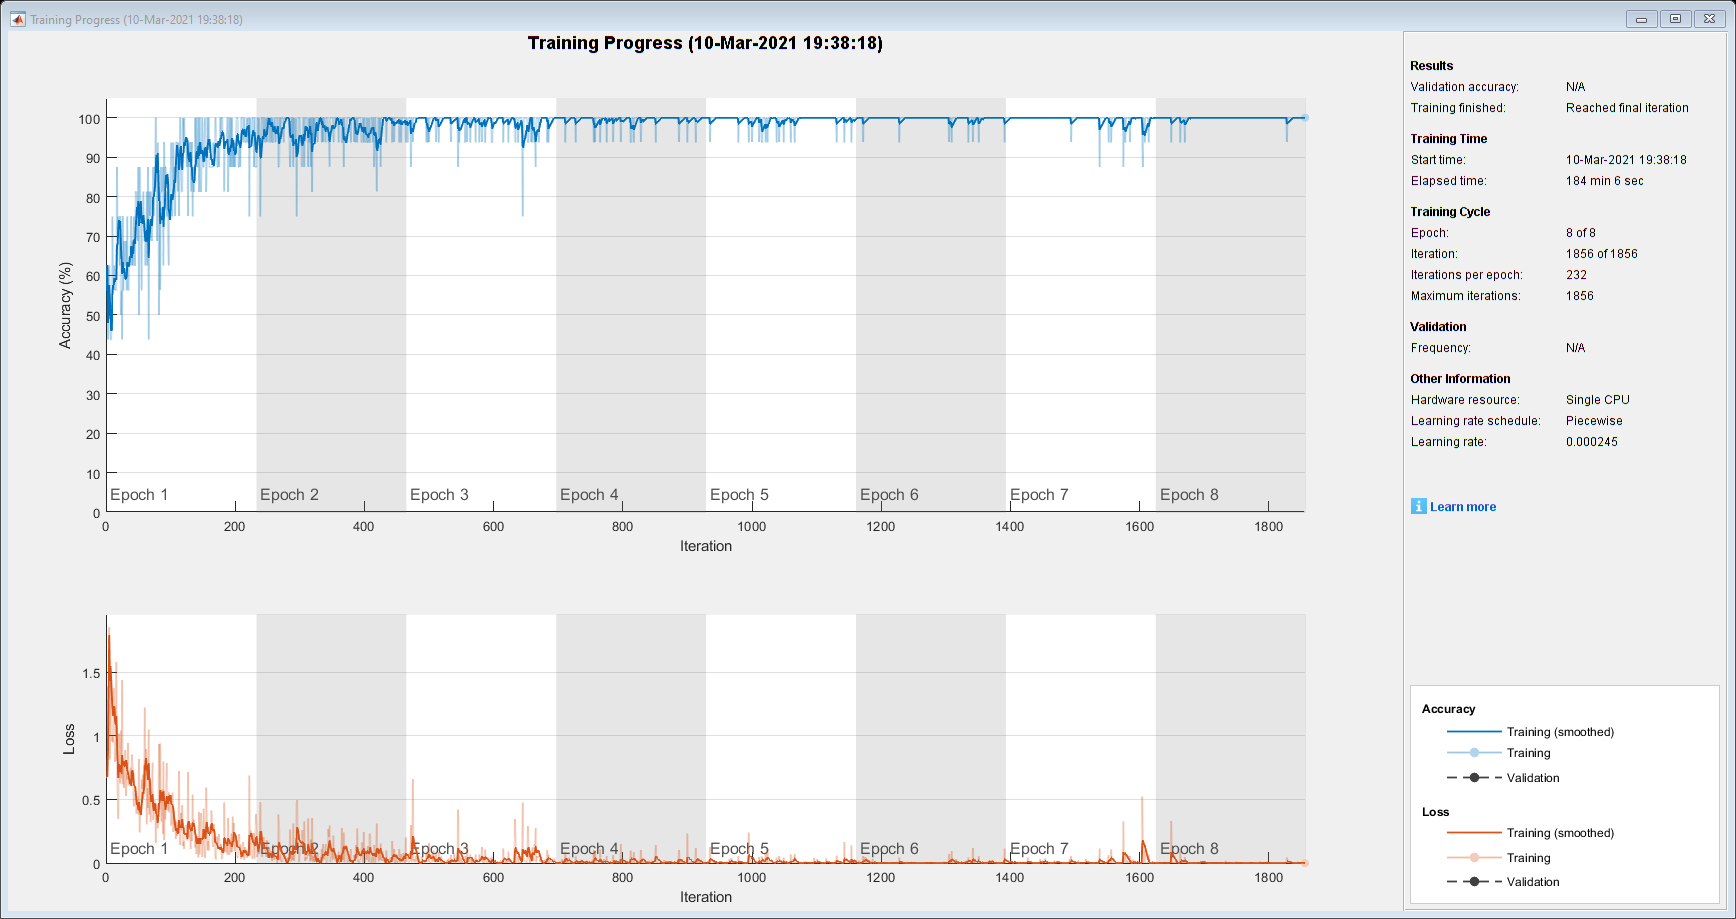

[net,info] = trainNetwork(Train_aug, lgraph, options);

## Submission

T = readtable('sampleSubmission.csv','Delimiter',',');
ids = T.Fingerprint;

preds_2 = {};
for i=1:numel(ids)
    imds = augmentedImageDatastore(imageSize,imageDatastore(['Test' filesep  ids{i}]));
    preds_2{end +1} = char(classify(net, imds)); 
end
submission = table(ids, preds_2', 'VariableNames', {'Fingerprint', 'Class'});
writetable(submission, 'SubmissionAlexNetMatlab_NoAug.csv','Delimiter', ',');
